## Prueba segundo parcial

### Gauss

A = [10 -7 -0; -3 2 6; 5 -1 5]

A =     10    -7     0
    -3     2     6
     5    -1     5


b = [4; 4; 6]

b =      4
     4
     6


x1 = linsolve(A,b)

x1 =     0.3097
   -0.1290
    0.8645


x2 = elimincacionGauss(A,b)

x2 =     0.3097
   -0.1290
    0.8645


### Factorización LU

A = gallery('dramadah', 6)

A =      1     1     0     1     0     0
     0     1     1     0     1     0
     0     0     1     1     0     1
     1     0     0     1     1     0
     1     1     0     0     1     1
     0     1     1     0     0     1


b1 = [0;0;0;1;0;0]

b1 =      0
     0
     0
     1
     0
     0


b2 = [0;0;0;0;0;1]

b2 =      0
     0
     0
     0
     0
     1


Con la Inversa (esto no nos gusta, sacaríamos 5)

B = inv(A)

B =     -1    -2    -3     4    -2     5
     1     1     1    -2     1    -2
    -1    -1    -2     3    -2     4
     1     1     2    -2     1    -3
     0     1     1    -1     1    -2
     0     0     1    -1     1    -1


x1 = B*b1

x1 =      4
    -2
     3
    -2
    -1
    -1


x2 = B*b2

x2 =      5
    -2
     4
    -3
    -2
    -1


Con Diagonal (esto si nos gusta, pero tan solo sacaríamos 6)

x3 = A\b1

x3 =      4
    -2
     3
    -2
    -1
    -1


x4 = A\b2

x4 =      5
    -2
     4
    -3
    -2
    -1


Con Factorización LU y antidiagonal, (sacaríamos 7)

[L,U,p,s]=LUps(A)

L =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     1    -1     1     1     0     0
     1     0     0     1     1     0
     0     1     0     0     1     1


U =      1     1     0     1     0     0
     0     1     1     0     1     0
     0     0     1     1     0     1
     0     0     0    -1     2    -1
     0     0     0     0    -1     2
     0     0     0     0     0    -1


p =      1     2     3     4     5     6


s = 1

Pb1 = b1(p)

Pb1 =      0
     0
     0
     1
     0
     0


Pb2 = b2(p)

Pb2 =      0
     0
     0
     0
     0
     1


x5 = U\(L\Pb1)

x5 =      4
    -2
     3
    -2
    -1
    -1


x6 = U\(L\Pb2)

x6 =      5
    -2
     4
    -3
    -2
    -1


Con Factorización LU y linsolve indicando matrices (sacaríamos 9)

%[...]

Si queremos sacar 10

Utilizamos factLu, rotamos b con p y luego resolvemos con nuestras funciones backsub y forsub.

Nota: hacer que nuestros backSub y ForSub puedan resolver matrices...

en lugar de b(1:i-1), lo hacemos b( ,i-1). O, en otras palabras, pedirle que lo haga para todas las columnas. 

%[...]


Ejercicio:

A = [2 1 5; 4 4 -4; 1 3 1]

A =      2     1     5
     4     4    -4
     1     3     1


b = [5; 0; 6]

b =      5
     0
     6



[L,U,p,s]=LUps(A)

L =     1.0000         0         0
    0.2500    1.0000         0
    0.5000   -0.5000    1.0000


U =      4     4    -4
     0     2     2
     0     0     8


p =      2     3     1


s = 1


Pb = b(p)

Pb =      0
     6
     5


y = forsub(L,Pb)

y =      0
     6
     8


x = backsub(U,y)

x =     -1
     2
     1



xrev = A\b

xrev =     -1
     2
     1


Determinante en una linea:

det = prod(diag(U))*s

det = 64

Estudiar matrix inversa con LU

A = [2 1 5; 4 4 -4; 1 3 1]

A =      2     1     5
     4     4    -4
     1     3     1


I = eye(3)

I =      1     0     0
     0     1     0
     0     0     1



[L,U,p,s]=LUps(A)

L =     1.0000         0         0
    0.2500    1.0000         0
    0.5000   -0.5000    1.0000


U =      4     4    -4
     0     2     2
     0     0     8


p =      2     3     1


s = 1


Pb = I(p,:)

Pb =      0     1     0
     0     0     1
     1     0     0


y = forsub(L,Pb)

y =          0    1.0000         0
         0   -0.2500    1.0000
    1.0000   -0.6250    0.5000


x = backsub(U,y)

x =     0.2500    0.2188   -0.3750
   -0.1250   -0.0469    0.4375
    0.1250   -0.0781    0.0625



inv(A)

ans =     0.2500    0.2188   -0.3750
   -0.1250   -0.0469    0.4375
    0.1250   -0.0781    0.0625


### Matriz Tridiagonal

n = 4

n = 4

unos = ones(n,1)

unos =      1
     1
     1
     1


e = -1*unos

e =     -1
    -1
    -1
    -1


f = 2.04*unos

f =     2.0400
    2.0400
    2.0400
    2.0400


g = -1*unos

g =     -1
    -1
    -1
    -1


r = [40.8;0.08;0.08;200.8]

r =    40.8000
    0.0800
    0.0800
  200.8000


%x = funcionTriDiagonal(e,f,g,r)

xres = [65.3279;92.4689;123.2287;158.8376]

xres =    65.3279
   92.4689
  123.2287
  158.8376


### Prueba Jacobi

A = [10 -1 2 0; -1 11 -1 3; 2 -1 10 -1; 0 3 -1 8]

A =     10    -1     2     0
    -1    11    -1     3
     2    -1    10    -1
     0     3    -1     8


b = [6;25;-11;15]

b =      6
    25
   -11
    15


x = zeros(length(b),1)

x =      0
     0
     0
     0


%x = [1 2 -1 1]'
imax = 2^51;
tol = 5*10^-5;
x1 = linsolve(A,b)

x1 =     1.0000
    2.0000
   -1.0000
    1.0000


x2 = A\b

x2 =     1.0000
    2.0000
   -1.0000
    1.0000


[x3, i] = jacobi2(A, b, x)

x3 =      1
     2
    -1
     1


i = 43

Parabola

qf = @(a,b,c,x) (1/2)*a*x.^2 -b*x +c

qf = function_handle with value:
    @(a,b,c,x)(1/2)*a*x.^2-b*x+c


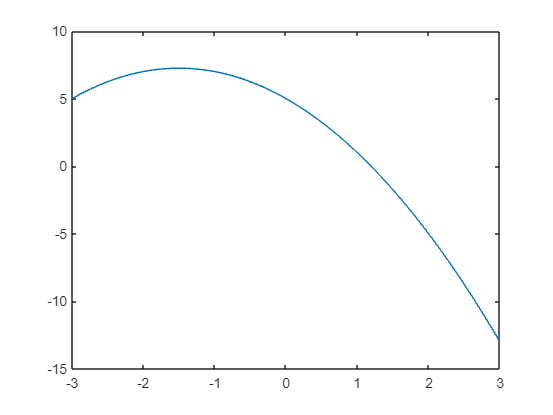

a = -2;
b = 3;
c = 5;
x = linspace(-3, 3);
f = qf(a,b,c,x);
plot(x,f)

Forma Matricial

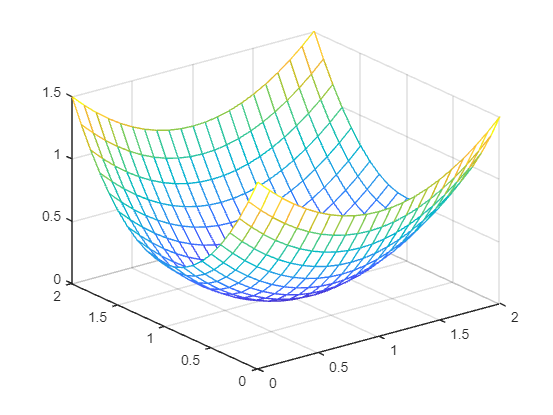

qf2 = @(A, b, c, x1, x2) ...
    (1/2)*(A(1,1)*x1.^2 + (A(1,2)+A(2,1))*x1.*x2 + A(2,2)*x2.^2) - (b(1)*x1 + b(2)*x2) + c;

A = [1 0; 0 2];
b = [1; 2];
c = 1.5;

x1 = 0:0.1:2;
x2 = x1;

[X1, X2] = meshgrid(x1, x2);

f2 = qf2(A,b,c,X1,X2);

mesh(X1, X2, f2)

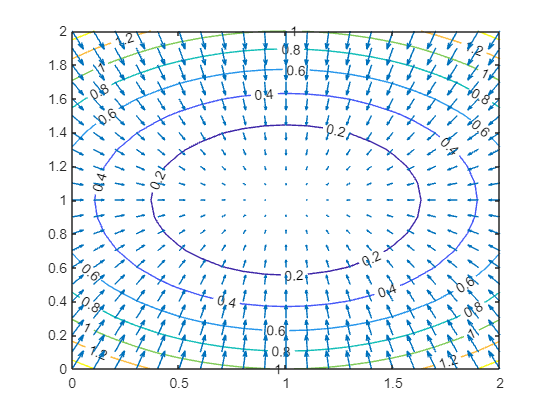


[cs, h] = contour(x1, x2, f2);
clabel(cs, h);
hold on
[fx1, fx2] = gradient(f2, 0.25);
quiver(x1, x2, -fx1, -fx2);
hold off